Consider the ridiculously simple IVP $u'=u$, $u(0)=1$, whose solution is $e^t$. 

dudt = @(t,u) u;
u_exact = @exp;
a = 0;  b = 1;

Let's apply the LIAF method to this problem for varying fixed step sizes. We'll measure the error at the time $t=1$. 

n = [5;10;20;40;60];
err = 0*n;
for j = 1:length(n)
    h = (b-a)/n(j);
    t = a + h*(0:n(j))';
    u = [1; u_exact(h); zeros(n(j)-1,1)];
    f = [dudt(t(1),u(1)); zeros(n(j)-2,1)];
    for i = 2:n(j)
        f(i) = dudt(t(i),u(i));
        u(i+1) = -4*u(i) + 5*u(i-1) + h*(4*f(i)+2*f(i-1));
    end
    err(j) = abs(u_exact(b) - u(end));
end

h = (b-a)./n;
table(n,h,err)

ans = 5×3 table
        n             h            err    
    __________    __________    __________

    5.0000e+00    2.0000e-01    1.6045e-02
    1.0000e+01    1.0000e-01    2.8455e+00
    2.0000e+01    5.0000e-02    1.6225e+06
    4.0000e+01    2.5000e-02    9.3442e+18
    6.0000e+01    1.6667e-02    1.7401e+32


The error starts out promisingly, but things explode from there. A graph of the last numerical attempt yields a clue.

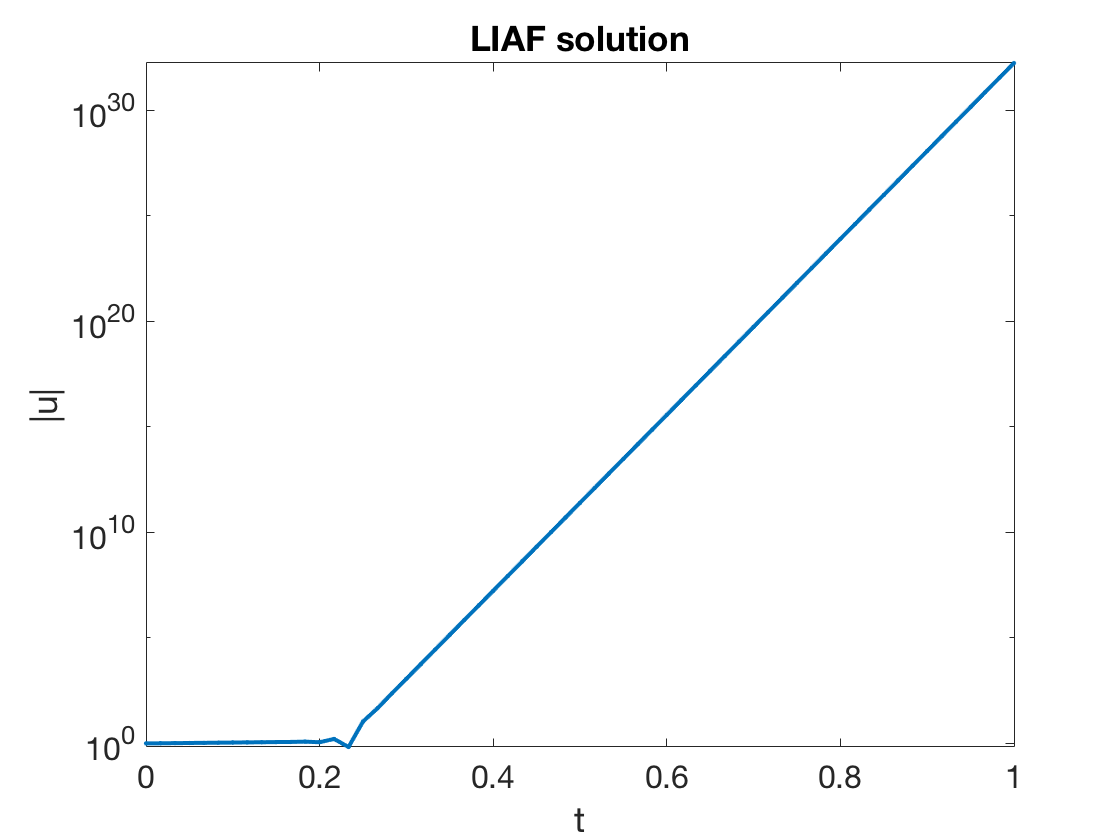

semilogy(t,abs(u),'.-')
xlabel('t'),  ylabel('|u|')  % ignore this line
title('LIAF solution'), axis tight   % ignore this line

It's clear that the solution is growing exponentially in time.